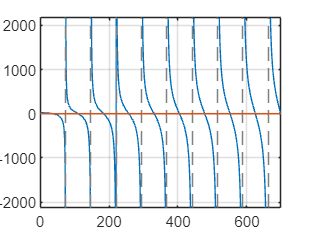

clc;clear;
num_2=4000; % the number of positive roots
H=0.042690748412273;
bn=[];
bn1=[];
bn2=[];
syms x;
parfor j=1:num_2-1 % solve roots of transcendental equations
    b=vpasolve(x*cot(x*H)==-0.5,3.1415926/H*j);
    bn(j)=double(b);

end

for i=1:length(bn)-1 % traverse roots
    if bn(i+1)-bn(i)>3.1415926/H+1 % Test for undercounting
        bn1(i)=double(vpasolve(x*cot(x*H)==-0.5,[bn(i)+3.1415926/H/50 bn(i+1)-3.1415926/H/50]));
    end
end
if ~isempty(bn1)
    bn=[bn,bn1]; % Roots of consolidation omissions
end

bn=sort(bn); % Roots in descending order

for i=1:length(bn)-1
    if bn(i+1)-bn(i)>3.1415926/H/50 % Test for repetitive roots
        bn2=[bn2,bn(i)];
    end
end
bn=bn2;
for i=1:length(bn)-1
    if bn(i+1)-bn(i)<3.1415926/H/50 % Test for repetitive roots
        disp(bn(i))
    end
end
% Image of transcendental equation
fplot(x*cot(x*H),[0 bn(10)])
hold on;
fplot(-0.5,[0 bn(10)])
grid on;
hold off


for i=1:length(bn)-1
    if bn(i+1)-bn(i)>3.1415926/H+3.1415926/H/50
        disp([num2str(bn(i)),'of line',num2str(i),'is wrong']) % Output problematic root locations

    end
end
% Save the file to the current folder
fid = fopen('bn.txt','wt');
fprintf(fid,'%f\n',bn); 
fclose(fid);